clear all

%% Parameters
tspan = 2014:0.1:2814;
numSim = 100;
alpha_P1_vals = 0.0:1:15.0;
homophily_ = 0.0;

peakTvsInteraction = tempvs_alphaP1_fmax_fixed(numSim, tspan, homophily_, alpha_P1_vals, 5.0);

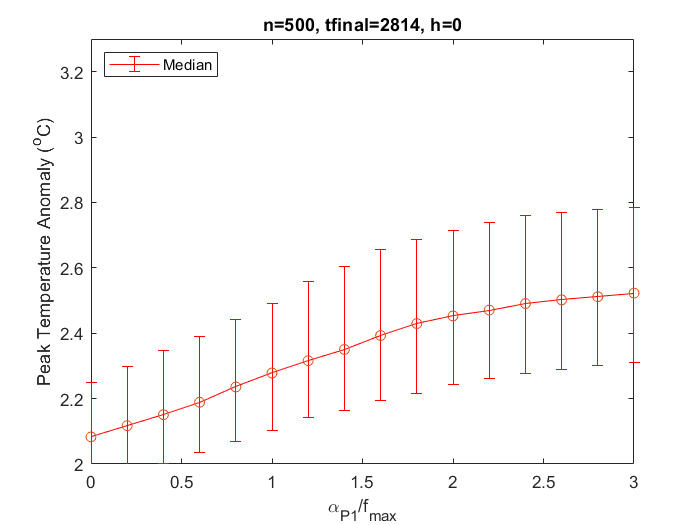

clf
medPeakT = median(peakTvsInteraction');
LowPeakT = quantile(peakTvsInteraction',0.25);
UpPeakT  = quantile(peakTvsInteraction',0.75);
temp_yneg = abs(medPeakT - LowPeakT);
temp_ypos = abs(medPeakT - UpPeakT);
errorbar((alpha_P1_vals)./5,medPeakT, temp_yneg, temp_ypos,'Color','red')
hold on
scatter((alpha_P1_vals)./5, medPeakT, 'Marker','o');

%stdPeakT = std(peakTvsInteraction');
%mnPeakT  = mean(peakTvsInteraction');
%errorbar(alpha_P1_vals./5, mnPeakT, stdPeakT)

ylabel("Peak Temperature Anomaly (^oC)")
xlabel("\alpha_{P1}/f_{max}")
legend("Median", "Location","northwest")
title("n=500, tfinal=2814, h=0")

ylim([2.0,3.3]);

hold off

peakTvsInteraction_heq1 = tempvs_alphaP1_fmax_fixed(numSim, tspan,1.0,alpha_P1_vals, 5.0);

simulation number = 10
Elapsed time is 380.761054 seconds.
simulation number = 20
Elapsed time is 411.893905 seconds.
simulation number = 30
Elapsed time is 412.876178 seconds.
simulation number = 40
Elapsed time is 413.530727 seconds.
simulation number = 50
Elapsed time is 411.177323 seconds.
simulation number = 60
Elapsed time is 416.053302 seconds.
simulation number = 70
Elapsed time is 413.576053 seconds.
simulation number = 80
Elapsed time is 408.924266 seconds.
simulation number = 90
Elapsed time is 410.881772 seconds.
simulation number = 100
Elapsed time is 409.781598 seconds.
simulation number = 110
Elapsed time is 411.223194 seconds.
simulation number = 120
Elapsed time is 389.531200 seconds.
simulation number = 130
Elapsed time is 414.997276 seconds.
simulation number = 140
Elapsed time is 409.957665 seconds.
simulation number = 150
Elapsed time is 410.202644 seconds.
simulation number = 160
Elapsed time is 412.691774 seconds.
simulation number = 170
Elapsed time is 413.19158

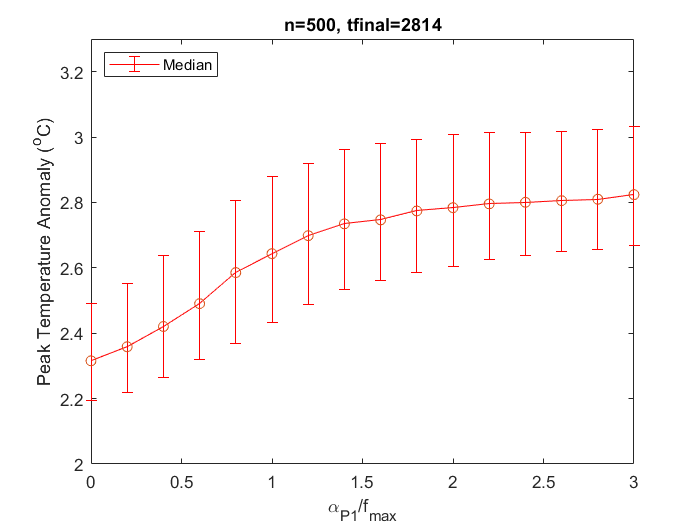

clf
medPeakT = median(peakTvsInteraction_heq1');
LowPeakT = quantile(peakTvsInteraction_heq1',0.25);
UpPeakT  = quantile(peakTvsInteraction_heq1',0.75);
temp_yneg = abs(medPeakT - LowPeakT);
temp_ypos = abs(medPeakT - UpPeakT);
errorbar(alpha_P1_vals./5,medPeakT, temp_yneg, temp_ypos,'Color','red')
hold on
scatter(alpha_P1_vals./5, medPeakT, 'Marker','o');

%stdPeakT = std(peakTvsInteraction_heq1');
%mnPeakT  = mean(peakTvsInteraction_heq1');
%errorbar(alpha_P1_vals./5, mnPeakT, stdPeakT)

ylabel("Peak Temperature Anomaly (^oC)")
xlabel("\alpha_{P1}/f_{max}")
legend("Median", "Location","northwest")
ylim([2.0,3.3]);
title("n=500, tfinal=2814")
hold off


%%% NOW DO TEMP VS. HOMOPHILY

hl = 0.0;
diffH = 0.1;
hu = 1.0;
hvals = 0.0:0.1:1.0;

peakTvsHom = tempvshomophily_fixed(numSim, tspan, hvals);

simulation number = 10
Elapsed time is 99.578285 seconds.
simulation number = 20
Elapsed time is 117.578663 seconds.
simulation number = 30
Elapsed time is 126.711870 seconds.
simulation number = 40
Elapsed time is 131.851752 seconds.
simulation number = 50
Elapsed time is 121.454198 seconds.
simulation number = 60
Elapsed time is 116.673015 seconds.
simulation number = 70
Elapsed time is 123.624765 seconds.
simulation number = 80
Elapsed time is 118.676784 seconds.
simulation number = 90
Elapsed time is 128.987259 seconds.
simulation number = 100
Elapsed time is 123.830784 seconds.


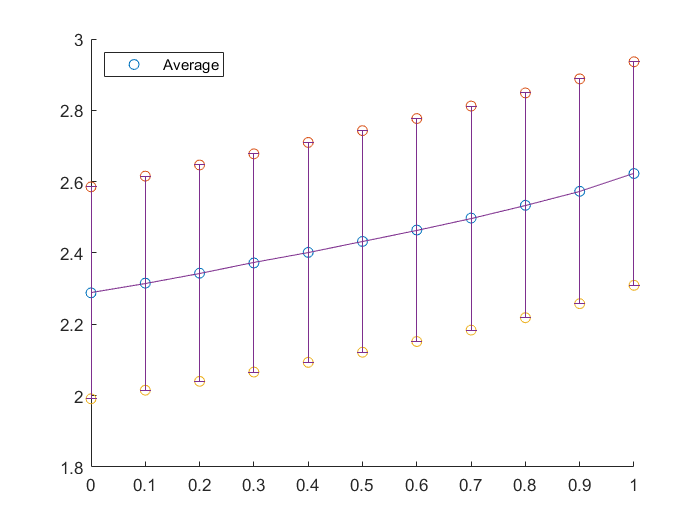

clf
avgPeakT = mean(peakTvsHom');
stdPeakT = std(peakTvsHom');
scatter(0:0.1:1, avgPeakT, 'Marker','o');
hold on
scatter(0:0.1:1, avgPeakT+stdPeakT, 'Marker', 'o');
scatter(0:0.1:1, avgPeakT-stdPeakT, 'Marker', 'o');
errorbar(0:0.1:1, avgPeakT,stdPeakT);
legend("Average", "Location","northwest")
hold off

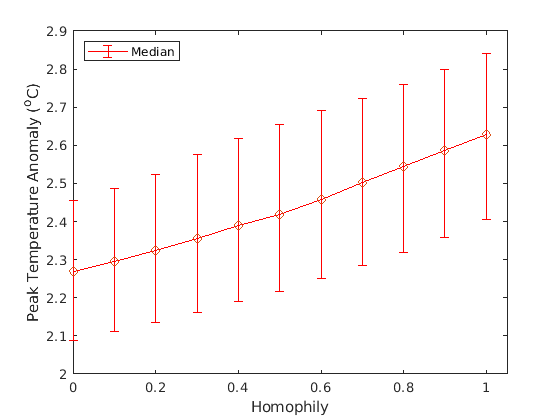

clf
medPeakT = median(peakTvsHom');
LowPeakT = quantile(peakTvsHom',0.25);
UpPeakT  = quantile(peakTvsHom',0.75);
temp_yneg = abs(medPeakT - LowPeakT);
temp_ypos = abs(medPeakT - UpPeakT);
errorbar(0:0.1:1,medPeakT, temp_yneg, temp_ypos,'Color','red')
hold on
scatter(0:0.1:1, medPeakT, 'Marker','o');

ylabel("Peak Temperature Anomaly (^oC)")
xlabel("Homophily")
xlim([0,1.05])
legend("Median", "Location","northwest")
%title("n=3000, tfinal=2814")
hold off

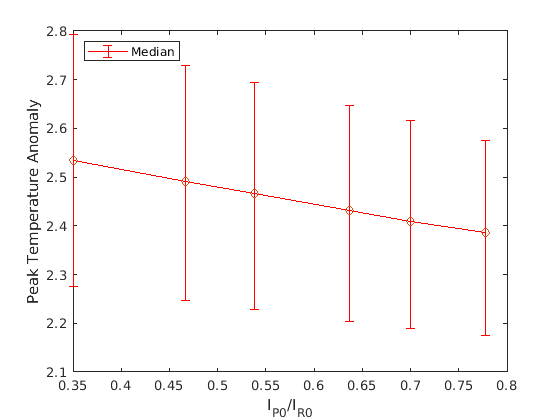

% peak temp anomaly vs. 'inequality'
clf
medPeakTvsIneq = median(peakTvsIneq');
LowPeakTvsIneq = quantile(peakTvsIneq',0.25);
UpPeakTvsIneq  = quantile(peakTvsIneq',0.75);
temp_ynegvsIneq = abs(medPeakTvsIneq - LowPeakTvsIneq);
temp_yposvsIneq = abs(medPeakTvsIneq - UpPeakTvsIneq);
errorbar(3.5./[0.9*5, 5, 1.1*5, 1.3*5, 1.5*5, 2*5],medPeakTvsIneq, temp_ynegvsIneq, temp_yposvsIneq,'Color','red')
hold on
scatter(3.5./[0.9*5, 5, 1.1*5, 1.3*5, 1.5*5, 2*5], medPeakTvsIneq, 'Marker','o');

ylabel("Peak Temperature Anomaly")
xlabel("I_{P0}/I_{R0}")

legend("Median", "Location","northwest")
%title("n=500, tfinal=2814")
hold off


1==a

Unrecognized function or variable 'a'.

temperature_vals = all_results.T;
bline_params_results = all_results.blineParams;
median_vals = quantile(temperature_vals', 0.5);
bot_five    = quantile(temperature_vals', 0.05);
top_five    = quantile(temperature_vals', 0.95);

clf
plot(all_results.pre2014(:,1), all_results.pre2014(:,end))
%plot(test_1751to2014(:,1), test_1751to2014(:,end))
hold on
%plot(tspan, avg_(:,end))
xlim([1900,max(tspan)])
ylim([0,8])
size(temperature_vals)

ans =         8001         500


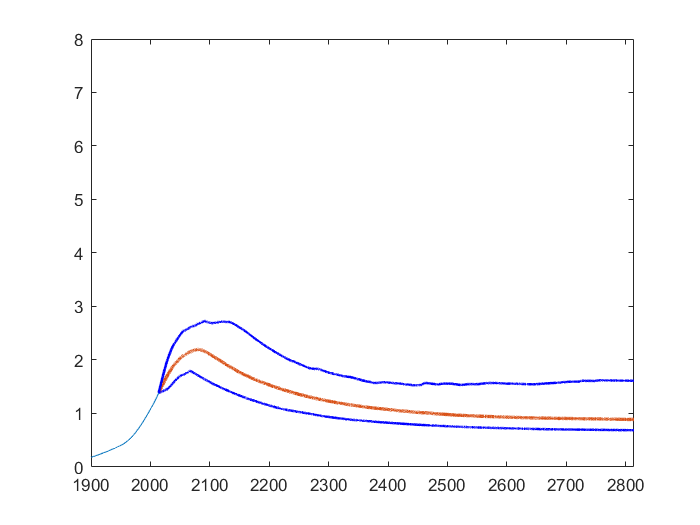


%plot(tspan, bline_params_results(:,end))
plot(tspan, median_vals, 'LineWidth', 2)
plot(tspan, top_five, 'LineWidth', 1.5, 'Color','b')
alpha(0.15);
plot(tspan, bot_five, 'LineWidth', 1.5, 'Color','b')

alpha(0.15);
%legend("pre2014","median", "top5", "bot5")

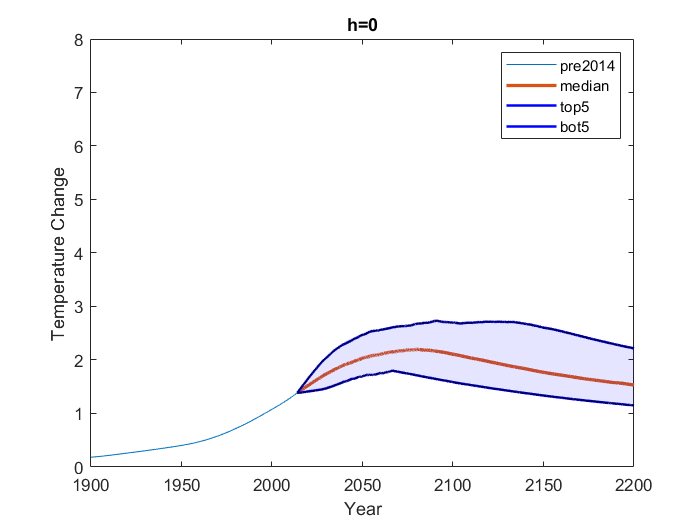

x2 = [tspan, fliplr(tspan)];
inBetween = [bot_five, fliplr(top_five)];
fill(x2, inBetween, 'b');
alpha(0.1);
xlabel('Year')
ylabel('Temperature Change')
title("h=0")
legend("pre2014","median", "top5", "bot5")

xlim([1900,2200])

temperature_vals_heq1 = all_results_heq1.T;

Unable to resolve the name all_results_heq1.T.

bline_params_results_heq1 = all_results_heq1.blineParams;
median_vals_heq1 = quantile(temperature_vals_heq1', 0.5);
bot_five_heq1    = quantile(temperature_vals_heq1', 0.05);
top_five_heq1    = quantile(temperature_vals_heq1', 0.95);

clf
plot(all_results_heq1.pre2014(:,1), all_results_heq1.pre2014(:,end))
%plot(test_1751to2014(:,1), test_1751to2014(:,end))
hold on
%plot(tspan, avg_(:,end))
xlim([1900,max(tspan)])
ylim([0,8])
size(temperature_vals_heq1)

%plot(tspan, bline_params_results(:,end))
plot(tspan, median_vals_heq1, 'LineWidth', 2)
plot(tspan, top_five_heq1, 'LineWidth', 1.5, 'Color','b')
alpha(0.15);
plot(tspan, bot_five_heq1, 'LineWidth', 1.5, 'Color','b')
alpha(0.15);
%legend("pre2014","median", "top5", "bot5")

x2 = [tspan, fliplr(tspan)];
inBetween_heq1 = [bot_five_heq1, fliplr(top_five_heq1)];
fill(x2, inBetween_heq1, 'b');
alpha(0.1);
xlabel('Year')
ylabel('Temperature Change')

xlim([1900,2200])

title("h=1")
legend("pre2014","median", "top5", "bot5")

xPvals = all_results.xPvals;
xRvals = all_results.xRvals;

median_vals_xP = quantile(xPvals', 0.5);
bot_five_xP    = quantile(xPvals', 0.05);
top_five_xP    = quantile(xPvals', 0.95);

median_vals_xR = quantile(xRvals', 0.5);
bot_five_xR    = quantile(xRvals', 0.05);
top_five_xR    = quantile(xRvals', 0.95);

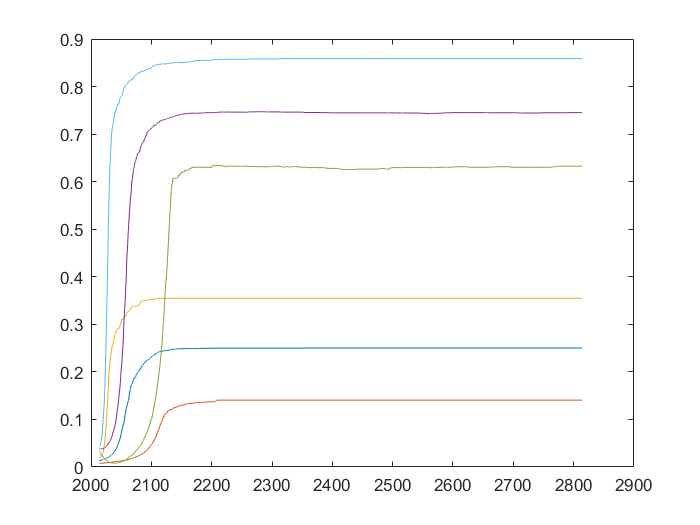

clf
plot(tspan, median_vals_xR)
hold on
plot(tspan, bot_five_xR)
plot(tspan, top_five_xR)

plot(tspan, median_vals_xP)
plot(tspan, bot_five_xP)
plot(tspan, top_five_xP)

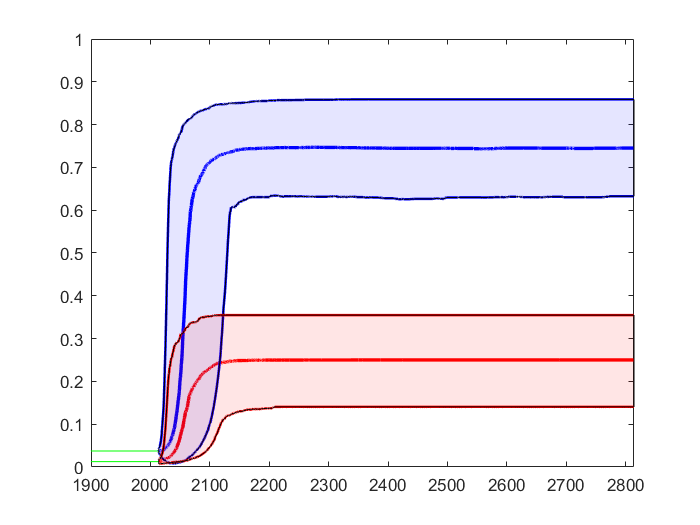

clf
len_ = size(all_results.pre2014(:,1));
zeros_ = ones((len_(1))).*(0.05*0.75);
plot(all_results.pre2014(:,1), zeros_, 'Color','g')
%plot(test_1751to2014(:,1), test_1751to2014(:,end))
hold on
%plot(tspan, avg_(:,end))
xlim([1900,max(tspan)])
ylim([0,1])
%size(temperature_vals)

%plot(tspan, bline_params_results(:,end))
plot(tspan, median_vals_xP, 'LineWidth', 2, 'Color', 'b')
plot(tspan, median_vals_xR, 'LineWidth', 2, 'Color', 'r')

plot(tspan, top_five_xP, 'LineWidth', 1.5, 'Color','b')
alpha(0.15);
plot(tspan, bot_five_xP, 'LineWidth', 1.5, 'Color','b')
alpha(0.15);
%legend("pre2014","median", "top5", "bot5")
x2 = [tspan, fliplr(tspan)];
inBetween_xP = [bot_five_xP, fliplr(top_five_xP)];
fill(x2, inBetween_xP, 'b');
alpha(0.1);

%%% Rich pop
plot(all_results.pre2014(:,1), zeros_.*(0.25/0.75), 'Color','g')
plot(tspan, top_five_xR, 'LineWidth', 1.5, 'Color','r')
alpha(0.15);
plot(tspan, bot_five_xR, 'LineWidth', 1.5, 'Color','r')
alpha(0.15);
%legend("pre2014","median", "top5", "bot5")
x2 = [tspan, fliplr(tspan)];
inBetween_xR = [bot_five_xR, fliplr(top_five_xR)];
fill(x2, inBetween_xR, 'r');
alpha(0.1);

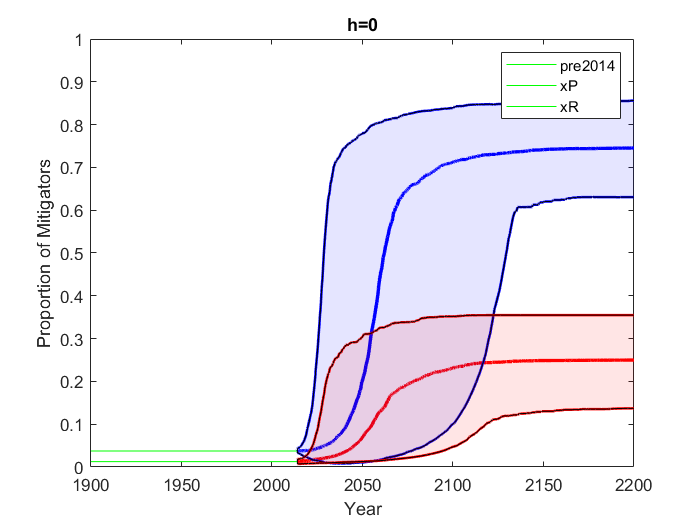

xlabel('Year')
ylabel('Proportion of Mitigators')
title("h=0")
legend("pre2014","xP", "xR")
xlim([1900,2200]);

xPvals = all_results_heq1.xPvals;
xRvals = all_results_heq1.xRvals;
xPvals = xPvals./(1-all_results_heq1.prop_R0);
xRvals = xRvals./all_results_heq1.prop_R0;

median_vals_xP = quantile(xPvals', 0.5);
bot_five_xP    = quantile(xPvals', 0.05);
top_five_xP    = quantile(xPvals', 0.95);

median_vals_xR = quantile(xRvals', 0.5);
bot_five_xR    = quantile(xRvals', 0.05);
top_five_xR    = quantile(xRvals', 0.95);
clear xPvals; clear xRvals;

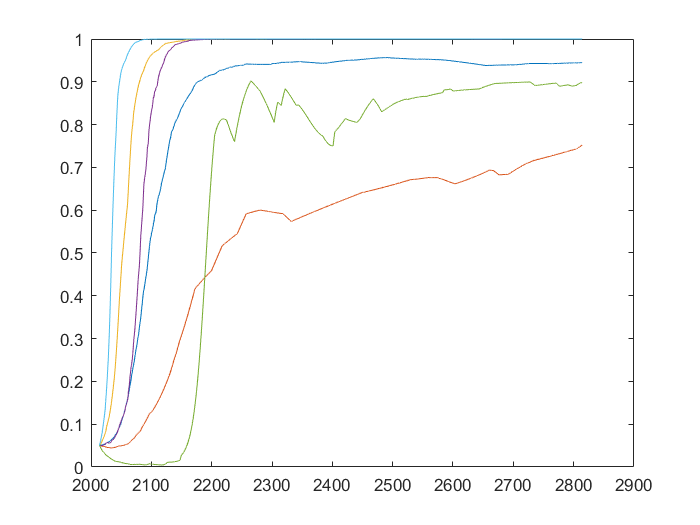

clf
plot(tspan, median_vals_xR)
hold on
plot(tspan, bot_five_xR)
plot(tspan, top_five_xR)

plot(tspan, median_vals_xP)
plot(tspan, bot_five_xP)
plot(tspan, top_five_xP)

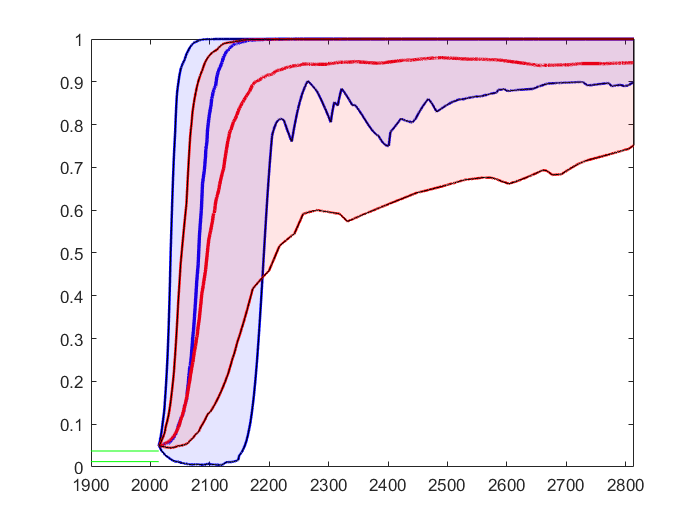

clf
len_ = size(all_results_heq1.pre2014(:,1));
zeros_ = ones((len_(1))).*(0.05*0.75);
plot(all_results_heq1.pre2014(:,1), zeros_, 'Color','g')
%plot(test_1751to2014(:,1), test_1751to2014(:,end))
hold on
%plot(tspan, avg_(:,end))
xlim([1900,max(tspan)])
ylim([0,1])
%size(temperature_vals)

%plot(tspan, bline_params_results(:,end))
plot(tspan, median_vals_xP, 'LineWidth', 2, 'Color', 'b')
plot(tspan, median_vals_xR, 'LineWidth', 2, 'Color', 'r')

plot(tspan, top_five_xP, 'LineWidth', 1.5, 'Color','b')
alpha(0.15);
plot(tspan, bot_five_xP, 'LineWidth', 1.5, 'Color','b')
alpha(0.15);
%legend("pre2014","median", "top5", "bot5")
x2 = [tspan, fliplr(tspan)];
inBetween_xP = [bot_five_xP, fliplr(top_five_xP)];
fill(x2, inBetween_xP, 'b');
alpha(0.1);

%%% Rich pop
plot(all_results_heq1.pre2014(:,1), zeros_.*(0.25/0.75), 'Color','g')
plot(tspan, top_five_xR, 'LineWidth', 1.5, 'Color','r')
alpha(0.15);
plot(tspan, bot_five_xR, 'LineWidth', 1.5, 'Color','r')
alpha(0.15);
%legend("pre2014","median", "top5", "bot5")
x2 = [tspan, fliplr(tspan)];
inBetween_xR = [bot_five_xR, fliplr(top_five_xR)];
fill(x2, inBetween_xR, 'r');
alpha(0.1);

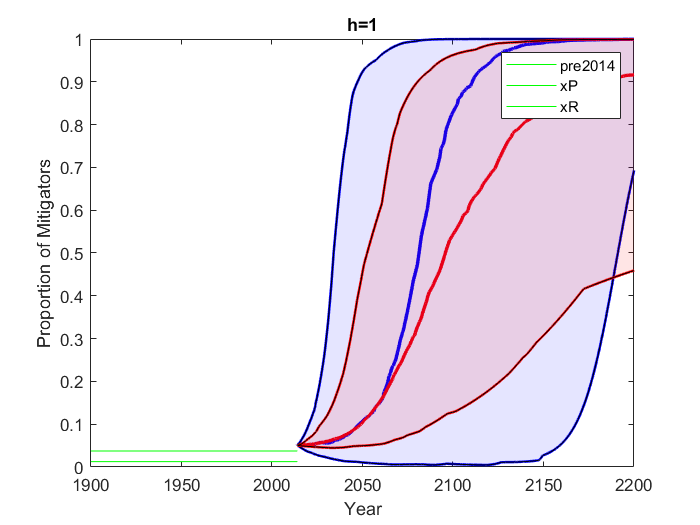

xlabel('Year')
ylabel('Proportion of Mitigators')
title("h=1")
legend("pre2014","xP", "xR")
xlim([1900,2200])